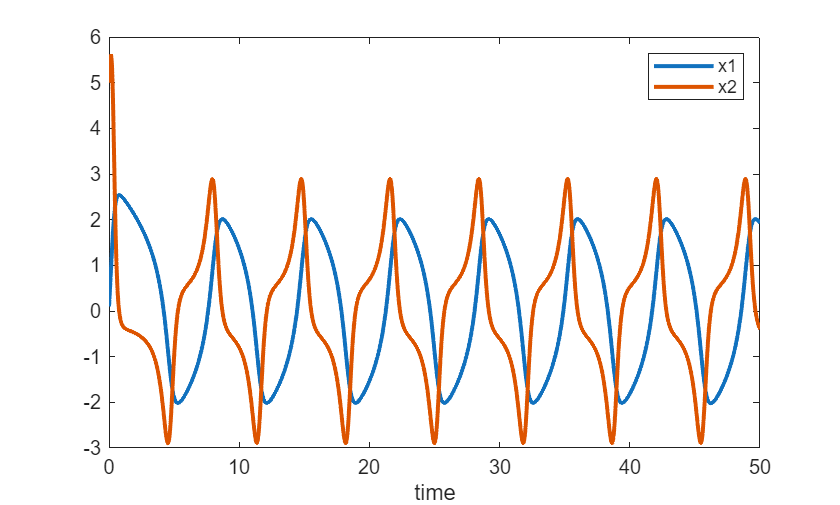

% This script constructs the underlying dynamical system of the Van der Pol
% oscillator, given time series measurements using SINDy.

% The underlying system is:
% y'' - mu(1-y^2)y' + y = 0

% You can rewrite this as a 2 element set, by letting:
    %x1 = y
    %x2 = y'
% resulting in: 
    %x1' = x2
    %x2' = mu(1-x1^2)x2 -x1 
%Expanding:
    %x1' = x2
    %x2' = mu*x2 - mu*(x1^2)x2 - x1
% this is what we will recover, from measurements of x1 and x2

clear all; close all; clc

%RHS function defined in rhs_dyn.m

%Define time points
dt = 0.01;
t = 0:dt:50;

%IC:
x0 = [0.1, 5];
%mu:
mu = 1.2;
%system (simulated measurements):
[t,y] = ode45('rhs_dyn', t,x0, [], mu);
figure;
plot(t, y(:,1), t, y(:,2), 'linewidth',[2]);
xlabel('time')
legend('x1', 'x2')

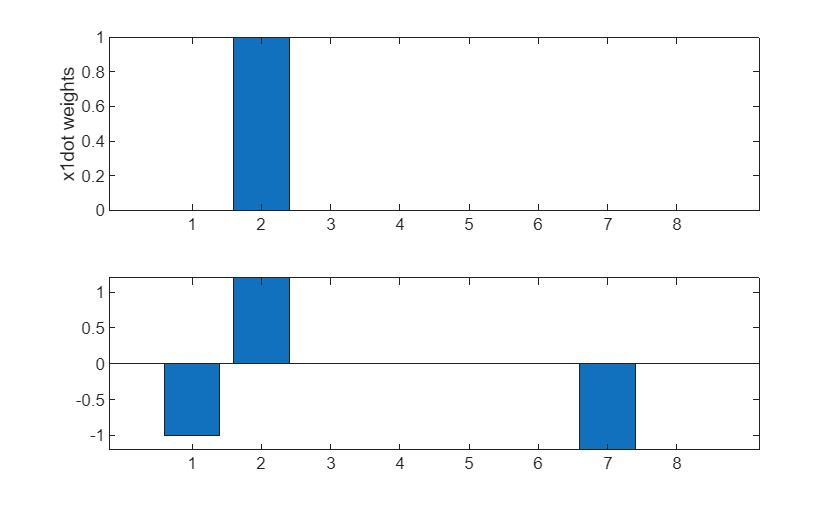

%% Now for model discovery
%The goal is now, purely given the OUTPUT of the above,
%Can we construct the van der pol equation?

x1 = y(:,1);
x2 = y(:,2);

%We need time derivatives, as we are working with y' = Theta*xi

n = length(t);
%centre difference for middle elements (not 1st and last pts). BAD but do what u gotta do
for j = 2:(n-1)
    x1dot(j-1) = (x1(j+1) - x1(j-1))/(2*dt);
    x2dot(j-1) = (x2(j+1) - x2(j-1))/(2*dt);
end

%Remove first and last elements so we just deal with centre diffs
x1s = x1(2:n-1);
x2s = x2(2:n-1);

%Now make lib of possible functions (let's just do polynomials up to deg(3):
A = [x1s, x2s, x1s.^2, x2s.^2, x1s.^3, (x2s.^2).*x1s, (x1s.^2).*x2s, x2s.^3];

%Recall we have 5000 data points. This means A is 5000x10 ie tall and
%skinny. You can easily solve it with pseudo inverse or backslash:

xi1 = A\x1dot.';
xi2 = A\x2dot.';

%visualize which elements of library are non-zero
figure;
subplot(2,1,1);
bar(xi1);
ylabel('x1dot weights')

subplot(2,1,2);
ylabel('x2dot weights')
bar(xi2);

From this bar chart, we can see that:

i. x1dot = 2nd element of A, namely x2. Thus x1dot = 1*x2 = x2 (True!)

ii. x2dot = -1* 1st el + 1.2* 2nd el -1.2*  7th el. Thus x2dot = -x1 + 1.2*x2 -1.2* (x1s^2)*x2

Which is: x2' = 1.2*x2 - 1.2*(x1^2)*x2 - x1 (recall mu = 1.2!)

Which is exactly the Van der Pol oscillator!!!

NOTE: The other elements on the bar are NOT ZERO. They are small, so to get rid, threshold them out

ALSO NOTE: try running by adding some noise to the dataset:

Noise effects:

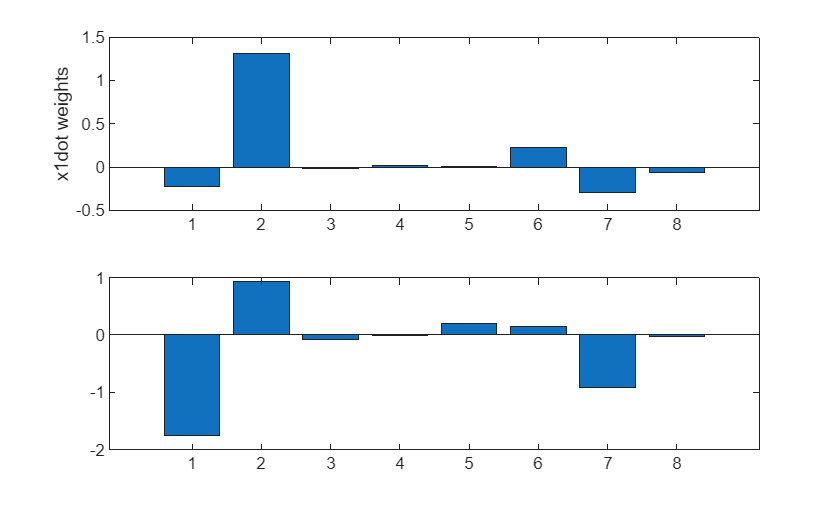

%add noise:
noise = 0.3;
x1 = y(:,1) + noise*randn(5001, 1);
x2 = y(:,2) + noise*randn(5001, 1);
n = length(t);

for j = 2:(n-1)
    x1dot(j-1) = (x1(j+1) - x1(j-1))/(2*dt);
    x2dot(j-1) = (x2(j+1) - x2(j-1))/(2*dt);
end

x1s = x1(2:n-1);
x2s = x2(2:n-1);
A = [x1s, x2s, x1s.^2, x2s.^2, x1s.^3, (x2s.^2).*x1s, (x1s.^2).*x2s, x2s.^3];
xi1 = A\x1dot.';
xi2 = A\x2dot.';
figure;
subplot(2,1,1);
bar(xi1);
ylabel('x1dot weights')

subplot(2,1,2);
ylabel('x2dot weights')
bar(xi2);